# Parte 2 - Controlo de servomecanismos de posição

#### Loading the data into matlab's environment.

data = load("data_aula8.mat"); 
data = data.data_aula8;

time_data = data.X.Data; % 1x2501 double
w_ref = double(data.Y(1).Data);
w_real = double(data.Y(3).Data);
s = tf('s');

-     `data.Y.(1) -> Reference angular velocity`

- `    data.Y.(2) -> Encoder readings`

- `    data.Y.(3) -> Real angular velocity readinds`

- `    data.Y.(4) -> Encoder readings as well? `   

## a) Erro em regime estacionário de posição para controladores proporcionais.

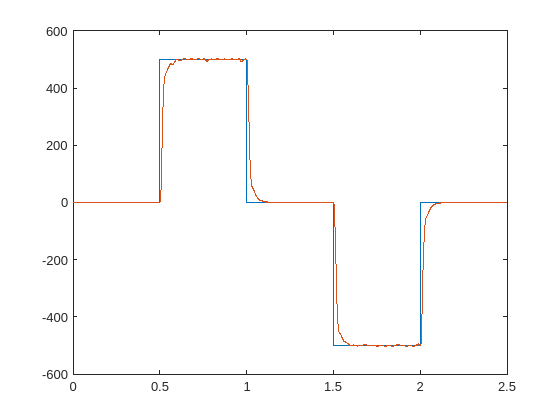


plot(time_data,w_ref);
hold on
plot(time_data,w_real);
hold off

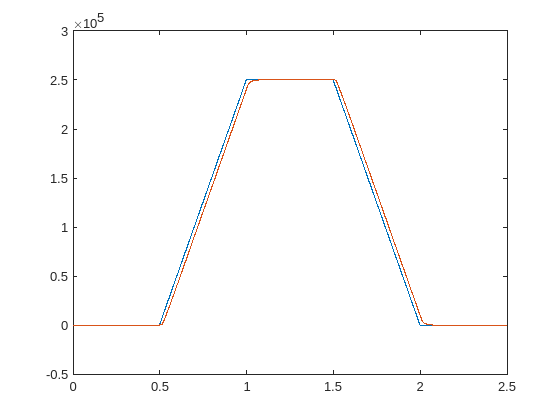

% Position is integral of velocity
delta_ref = cumsum(w_ref);
delta_real = cumsum(w_real);

plot(time_data,delta_ref);
hold on
plot(time_data,delta_real);
hold off

average_w_ref = max(delta_ref)

average_w_ref = 250000

average_w_real = mean(delta_real(time_data>1.15 & time_data<1.45))

average_w_real = 2.5026e+05

error_steady_state = abs(average_w_real-average_w_ref)

error_steady_state = 255.9832

error_percentile = error_steady_state/average_w_ref * 100

error_percentile = 0.1024

## b) Visualize pole map for closed loop function based on real data

tm = linspace(time_data(1),time_data(end),2501)';
dt = tm(2)-tm(1);
% Entrada em degrau
u   = w_ref';
%Saída do sistema
ym  = w_real';
% Definição de estrutura de dados para a função tfest: 
tt=timetable(u,ym,'Timestep',seconds(dt));

% Identificação de um sistema de 2ª ordem sem zeros
G_velocity=tfest(tt,2,0);
G_position = G_velocity*(1/s)

G_position =
 
  From input to output "ym":
            1.07e04
  ---------------------------
  s^3 + 195.6 s^2 + 1.07e04 s
 
Continuous-time transfer function.



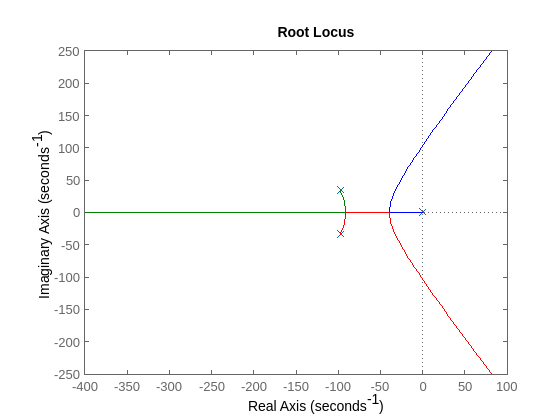

%pzmap(G_position);
rlocus(G_position) % To check sys parameters, rlocus has to be executed in command window

## c) Identifying limits for stability varying gain *K*

G_pos_den = G_position.Denominator

G_pos_den = 1×1 cell array
    {[1 195.5848 1.0704e+04 0]}


syms EPS k;
manual_array = [1 1.956e2 1.07e4 1.07e4*k];

This array results from the closed loop of K*G --> KG/1+KG, with G being *G_position*

routh_table = (routh(manual_array,EPS))

$$routh\_table = \left(\begin{array}{cc} 1 & 10700\\ \frac{978}{5} & 10700\,k\\ 10700-\frac{26750\,k}{489} & 0\\ \frac{57245000\,k\,\left(5\,k-978\right)}{489\,\left(\frac{26750\,k}{489}-10700\right)} & 0 \end{array}\right)$$

vpa(solve(routh_table(3)>0,k,'IgnoreAnalyticConstraints', true))

$$ans = 194.6$$

vpa((solve(routh_table(4)>0,k,'IgnoreAnalyticConstraints', true)))

$$ans = \left(\begin{array}{c} 196.6\\ 1.0 \end{array}\right)$$

This results say that for the system to be stable, K has to be bigger than 196,6, which matches up both rlocus and the alternative method below using *poles.*

break_nested_flag = false;

for k=1:300 
    feedback_G_pos = feedback(G_position*k,1);
    poles = pole(feedback_G_pos);

    for i=1:length(poles)
        %real(poles(i))
        if real(poles(i))>0
            break_nested_flag = true;
            break
        end
    end
    
    if break_nested_flag
        break %% This is just a workaround to break out of nested loops
    end
end

fprintf("The system is stable with k from 0 to %d\n",k);

The system is stable with k from 0 to 196


**On the other hand, this result seems to match the rlocus behaviour, which is good.**

## **d) Control the system in closed loop with gain K**

By varying the variable K and re running, we can see different behaviours, from slower to more rapid with overshoot to unstable (K>196)

K=17 is the higher the system can hold without overshoot(critical damping)(Seen in rlocus)

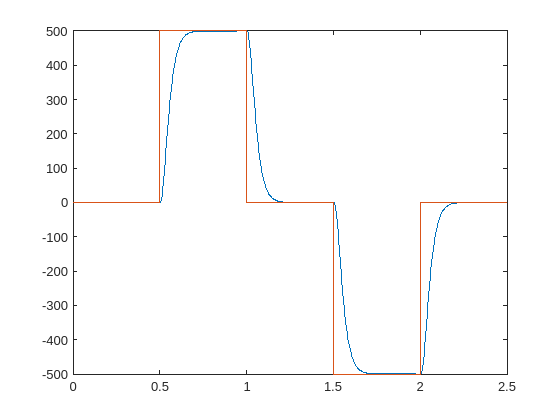

K = 17;
feedback_G_pos = feedback(G_position*K,1);

t = linspace(0,2.5,1000);
u = zeros(size(t));
u(t>0.5 & t<1) = 500;
u(t>1.5 & t<2) = -500;


[y, t] = lsim(feedback_G_pos,u,t);  % simulate the response of the transfer function to the input
plot(t, y)  % plot the output
hold on
plot(t,u);
hold off

## e) Use Routh Hurwitz method to prove that for C(s) = K(s+10), the system is always stable


$$\Delta s=1+\mathit{\mathbf{C}}\ldotp G$$
    
$$\Delta s=\textrm{s³}+195\ldotp 6\ldotp \textrm{s²}+10700\ldotp \left(k+1\right)\ldotp s+10700k$$
    
$$C\left(s\right)=k*\left(s+1\right)$$


syms EPS k;
caracteristic_eq_coefs = [1 195.6 10700*(k+1) 107000*k];
routh_table_d = routh(manual_array,EPS)

$$routh\_table\_d = \left(\begin{array}{cc} 1 & 10700\\ \frac{978}{5} & 10700\,k\\ 10700-\frac{26750\,k}{489} & 0\\ \frac{57245000\,k\,\left(5\,k-978\right)}{489\,\left(\frac{26750\,k}{489}-10700\right)} & 0 \end{array}\right)$$

vpa(solve(routh_table_d(3)>0,k,'IgnoreAnalyticConstraints', true))

$$ans = 194.6$$

vpa((solve(routh_table_d(4)>0,k,'IgnoreAnalyticConstraints', true)))

$$ans = \left(\begin{array}{c} 196.6\\ 1.0 \end{array}\right)$$

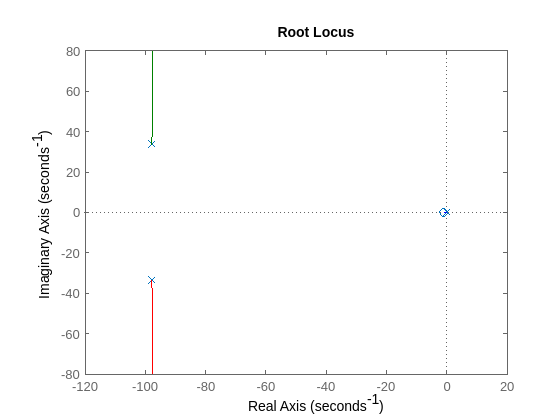

rlocus(G_position*(s+1))

This routh table isnt giving accurate results, even though we can prove the hypothesis is correct with rlocus, for any given K, the system is stable.

## f) Prove the system isn't always stable for C(s) = K*(s+z) with z<-p1-p2

zpk(G_position)

ans =
 
  From input to output "ym":
            10698
  --------------------------
  s (s^2 + 195.6s + 1.07e04)
 
Continuous-time zero/pole/gain model.



poles_position = roots(G_pos_den{1})

poles_position =    0.0000 + 0.0000i
 -97.7924 +33.7662i
 -97.7924 -33.7662i


It's a little confusing as the poles have imaginary part,what does it actually mean for p1 being bigger/smaller than p2 exactly?

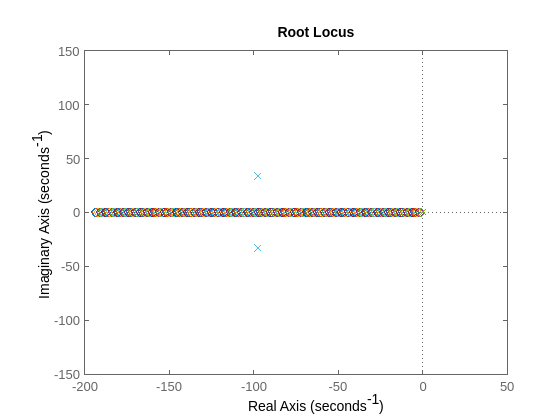


for z=-(-97)-(-97):-1:0
    rlocus(G_position*(s+z),1) % This is equivalent to C(s) = k*(s+z)
    hold on
end
    hold off

We can see that no matter the pole position, from -p1-p2 to 0,the poles never cross the imaginary axis, which means its stable no matter the pole position as long as the condiction z<-p1-p2 is met.